# MATLAB Onramp PoliMi

In questo live-script troverete un elenco dei comandi aggiuntivi che vi potranno essere utili nei corsi che affronterete qui al Poli.

Per eseguire il codice nelle sezioni grigio scuro premete il pulsante "Run Section" nella barra superiore oppure utilizzate la combinazione di comandi ctrl + ↵ (cmd + ↵  su Mac). 

## Calclolo simbolico

Per questa parte è necessario il **symbolic toolbox** che potete installare nella sezione "Add-Ons" nel menu Home. Oppure **lanciate il comado e cliccate sul nome sottolineato nel messaggio di errore**

syms x y;       % svariabili simboliche
f = (sin(x))^2  % non è necessario mettere la @ 

$$f = {\sin\left(x\right)}^{2}$$


df = diff(f)            % derivata prima di f

$$df = 2\,\cos\left(x\right)\,\sin\left(x\right)$$

df_2 = diff(f, x, 2)    % derivata seconda, x si può omettere in funzioni ad una variabile

$$df\_2 = 2\,{\cos\left(x\right)}^{2}-2\,{\sin\left(x\right)}^{2}$$


intf = int(f)           % integrale indefinito

$$intf = \frac{x}{2}-\frac{\sin\left(2\,x\right)}{4}$$


int_def = int(f, -1, 1)     % integrale definito dal -1 a 1

$$int\_def = 1-\frac{\sin\left(2\right)}{2}$$


% anche integrali impropri:
g = 1/x^2;
int_2 = int(g, 1, +inf)

$$int\_2 = 1$$

#### Limiti

 syms a h x;
 l1 = limit(sin(a*x)/x)                 % limiti notevoli

$$l1 = a$$

 
 l2 = limit((sin(x+h)-sin(x))/h, h, 0)  % limite per h -> 0

$$l2 = \cos\left(x\right)$$

 
 l3 = limit(1/x, x, 0, "right")         % limite destro per x -> 0 

$$l3 = \infty$$

#### Taylor

syms x;
f=sin(x)

$$f = \sin\left(x\right)$$

xbar=0;     % centro dell'espansione
k=5;        % ordine dell'espansione
Tf=taylor(f, x, xbar, 'order', k+1)     % sviluppo all'ordine k (k+1 è l'ordine del resto)

$$Tf = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

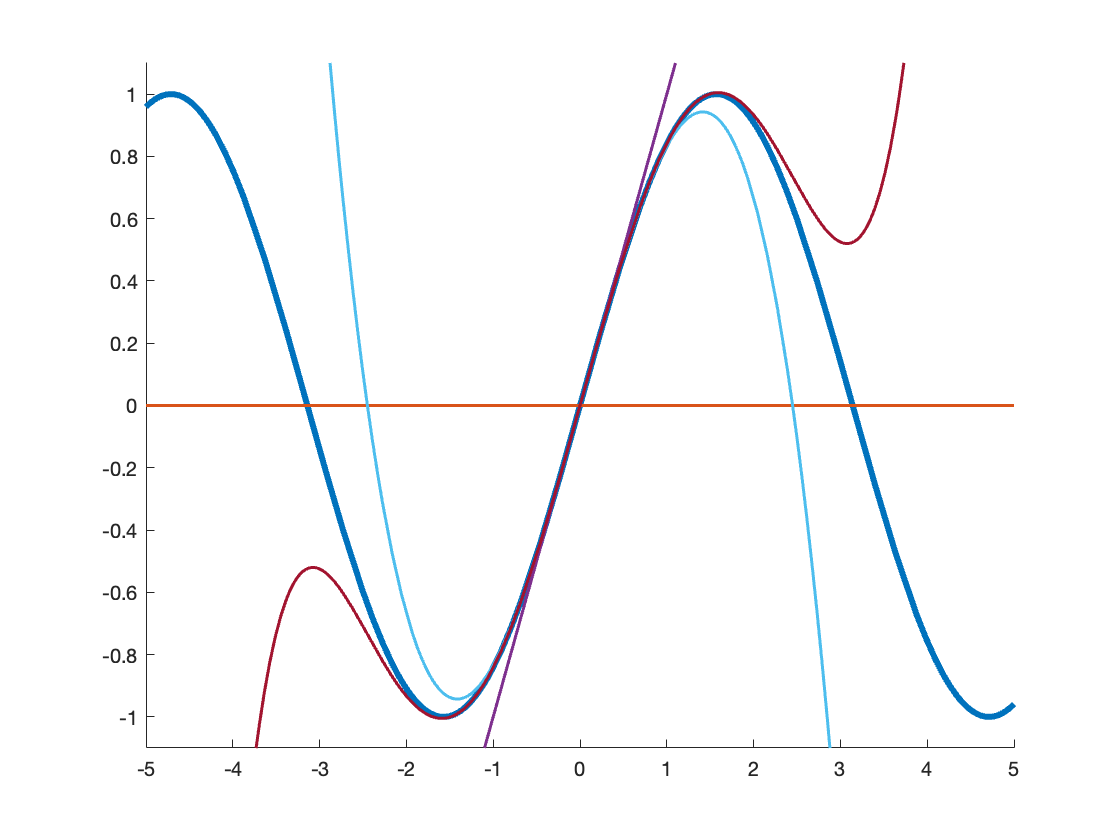

figure 
hold all
fplot(f, "LineWidth",3)
for ii=1:k+1            % animazione che mostra il miglioranento dell'approssiamzione all'aumentare dell'ordine
    Tf=taylor(f, x, xbar, 'order', ii);
    fplot(Tf, "LineWidth",1.5)
    ylim ([-1.1 1.1])
    pause(1)
end

#### Risoluzione di equazioni e sistemi

syms x;
% risolvere equazioni
eq = exp(2*x)+3*exp(x) == 54

$$eq = {\mathrm{e}}^{2\,x}+3\,{\mathrm{e}}^{x}=54$$

s = solve(eq)

$$s = \left(\begin{array}{c} \log\left(6\right)\\ \log\left(9\right)+\pi \,\mathrm{i} \end{array}\right)$$


% risolvere sistemi di equazioni
syms x y;
eq1= 6*x+2*y ==14; 
eq2= 3*x+7*y == 31;
[x_sol, y_sol]=solve(eq1,eq2)

$$x\_sol = 1$$

$$y\_sol = 4$$


% risolvere sistemi di equazioni differenziali
syms f(t) g(t)
S = dsolve(diff(f) == f + g, diff(g) == -f + g,f(0) == 1,g(0) == 2)

S = struct with fields:
    g: [1×1 sym]
    f: [1×1 sym]


S.f

$$ans = {\mathrm{e}}^{t}\,\cos\left(t\right)+2\,{\mathrm{e}}^{t}\,\sin\left(t\right)$$

S.g

$$ans = 2\,{\mathrm{e}}^{t}\,\cos\left(t\right)-{\mathrm{e}}^{t}\,\sin\left(t\right)$$

## Funzioni in due variabili e superfici

Questo tipo di problema può essere trattato anche con il pacchetto simbolico ma per i corsi del PoliMi verrà affrontato in questo modo:

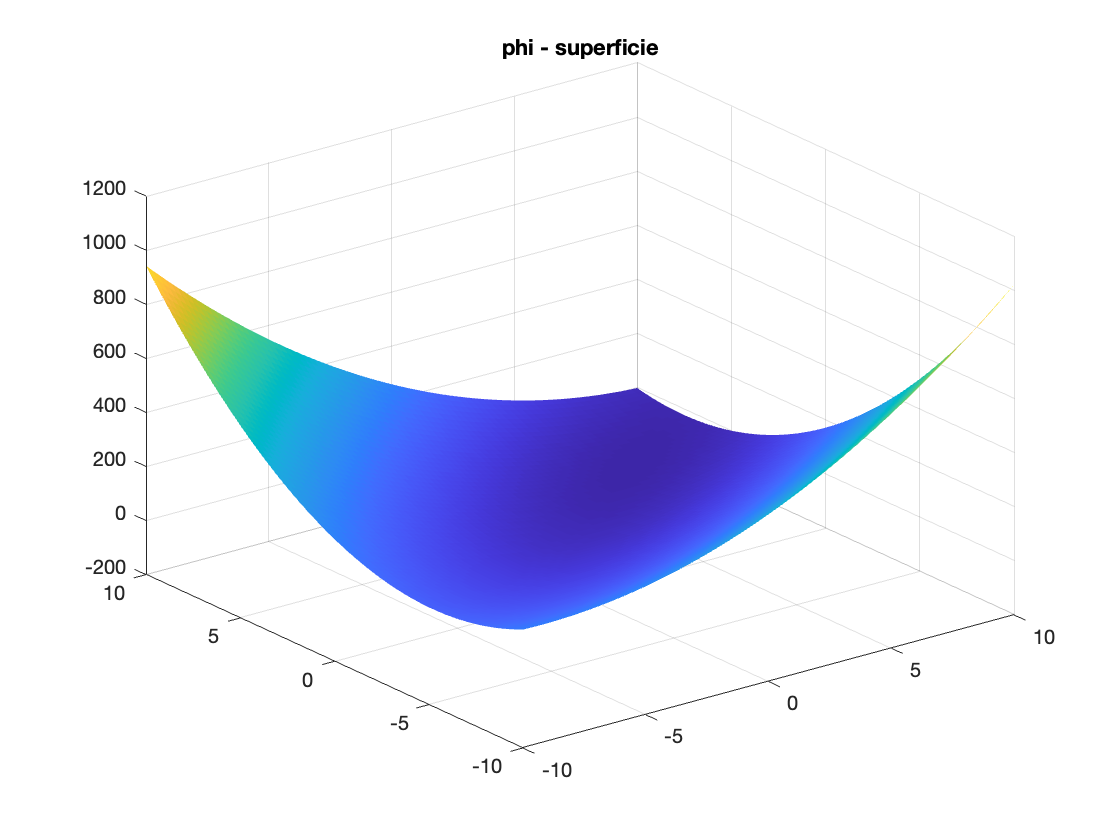

% Creazione della griglia (necessario per plot 2d)
x=linspace(-10,10,80);
y=linspace(-10,10,80);
[X,Y]=meshgrid(x,y);

% Esempio di funzione in 2 variabili
A = [4.24, -4.32; -4.32, 6.76];
b=[4 ; 8];
Phi = 0.5* ( A(1,1)*X.^2 + A(2,2)*Y.^2 + 2*A(1,2)*X.*Y ) - b(1)*X - b(2)*Y;

% Plot della superficie
figure();
surf(X,Y,Phi,'Lines','no');
title('phi - superficie')

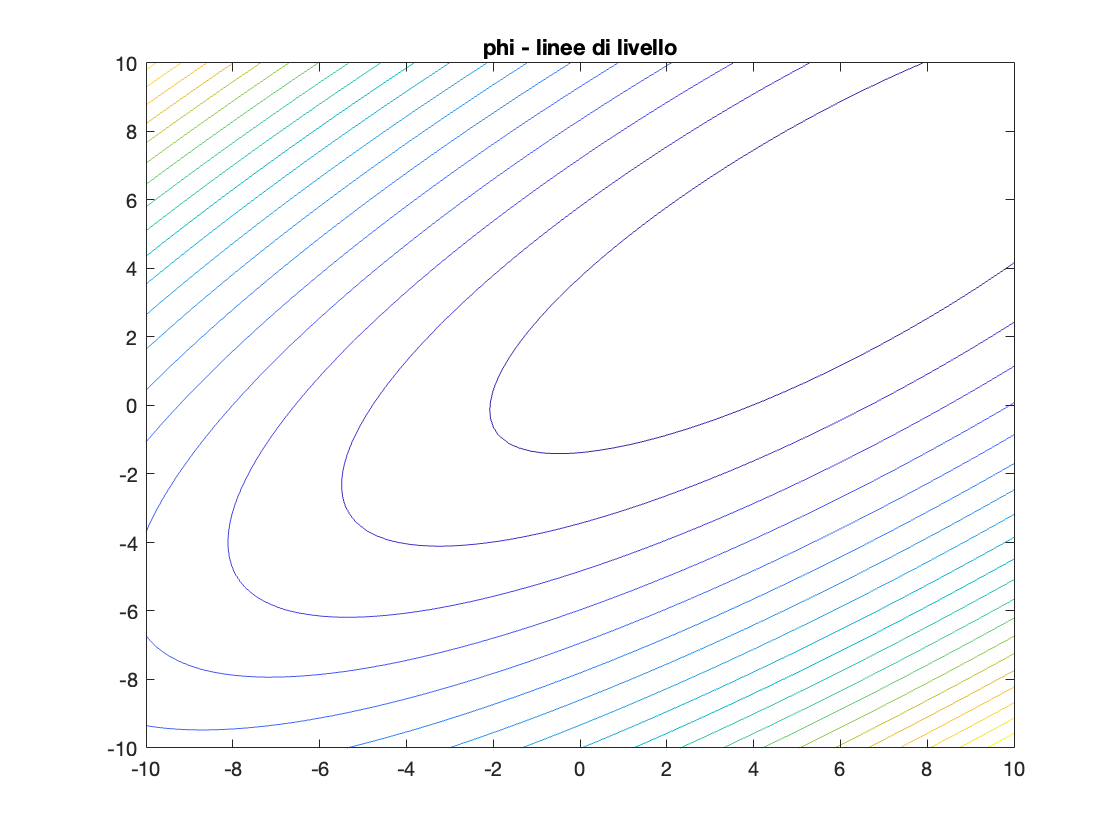


% Plot delle curve di livello
figure()
contour(X,Y,Phi,20)
hold on
title('phi - linee di livello')

## Algebra lineare

A = [2 3 4; 3 4 5; 4 5 2]

A =      2     3     4
     3     4     5
     4     5     2



det_A = det(A)      % calcola il determinante di A

det_A = 4


l = eig(A)          % calcola gli autovalori di A (risultato in ordine crescente)

l =    -2.6710
   -0.1385
   10.8096



[V, L] = eig(A)     % le colonne di V sono gli autovettori realtivi agli autovalori

V =     0.4248    0.7632    0.4869
    0.4128   -0.6420    0.6461
   -0.8057    0.0734    0.5878


L =    -2.6710         0         0
         0   -0.1385         0
         0         0   10.8096


                    % L è la matrice che ha sulla diagonale gli autovalori 
                    
b = [1; 2; 3];

x = A \ b           % Risolve il sistema A x = b;

x =      2
    -1
     0
